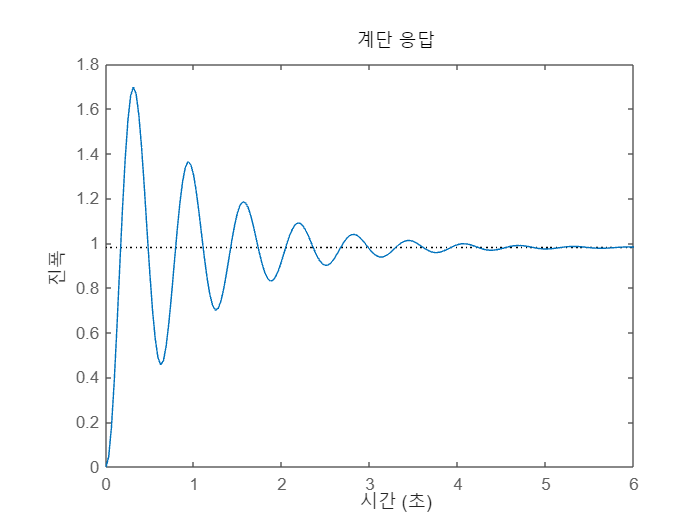

clear all
syms s
K = (sqrt(5)-1)/4;
Ls = 1/(s^2 + 2*s + 2);
[n, d] = numden(Ls/(1+Ls));
num1 = sym2poly(n);
den1 = sym2poly(d);
sys_dis = tf(num1, den1);
step(sys_dis);

S = stepinfo(sys_dis);
PO = S.Overshoot     % 단위[%]

PO = 73.1454

Ts = S.SettlingTime  % 단위[초]

Ts = 3.8053